# Create Structure Array

This example shows how to create a structure array. A structure is a data type that groups related data using data containers called fields. Each field can contain data of any type or size.

Store a patient record in a scalar structure with fields `name`, `billing`, and `test`.

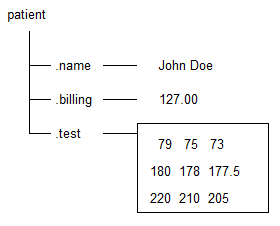

patient(1).name = 'John Doe';
patient(1).billing = 127.00;
patient(1).test = [79, 75, 73; 180, 178, 177.5; 220, 210, 205];
patient

Add records for other patients to the array by including subscripts after the array name.

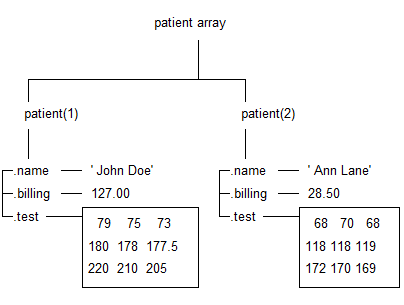

patient(2).name = 'Ann Lane';
patient(2).billing = 28.50;
patient(2).test = [68, 70, 68; 118, 118, 119; 172, 170, 169];
patient

Each patient record in the array is a structure of class `struct`. An array of structures is often referred to as a struct array. Like other MATLAB arrays, a struct array can have any dimensions.

A struct array has the following properties:

- All structs in the array have the same number of fields.

- All structs have the same field names.

- Fields of the same name in different structs can contain different types or sizes of data.

Any unspecified fields for new structs in the array contain empty arrays.

patient(3).name = 'New Name';
patient(3)

Access data in the structure array to find how much the first patient owes, and to create a bar graph of his test results.

amount_due = patient(1).billing
bar(patient(1).test)
title(['Test Results for ', patient(1).name])

*Copyright 1984-2017 The MathWorks, Inc.*